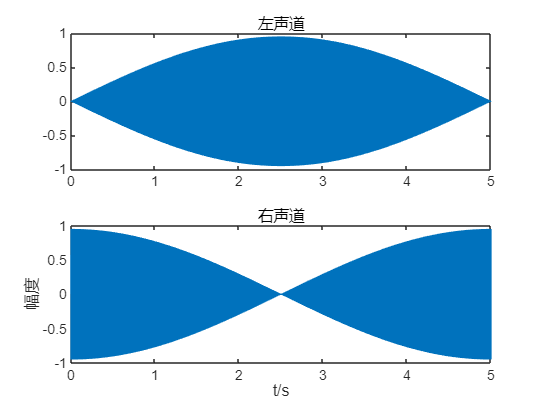

% 清除工作区和命令窗口
clc;clear;

% 设置基本参数
A=1;                    % 信号幅度
f=800;                  % 信号频率(Hz)
Fs=10*f;                % 采样频率，设为信号频率的10倍，满足采样定理
N=5*Fs;                 % 采样点数，采样5秒的数据
t=(0:N-1)/Fs;          % 生成时间序列，范围为0到5秒

% 生成基本正弦信号
x=A*sin(2*pi*f*t);     % 生成频率为800Hz的正弦波

% 生成立体声信号
s1=x.*sin(0.1*2*pi*t); % 左声道信号：原始信号与0.1Hz的正弦波相乘
s2=x.*cos(0.1*2*pi*t); % 右声道信号：原始信号与0.1Hz的余弦波相乘

% 播放立体声信号
sound([s1',s2'],Fs);   % 将左右声道组合播放，注意需要转置为列向量

% 绘制时域波形
figure;
subplot(2,1,1);        % 创建2行1列的子图，选择第1个
plot(t,s1);           % 绘制左声道波形
title('左声道');
subplot(2,1,2);        % 选择第2个子图
plot(t,s2);           % 绘制右声道波形
title('右声道');
xlabel('t/s');         % x轴标签
ylabel('幅度');        % y轴标签